Plotting the derivative of lhet with respect to t and lhet. This equation was derived by taking the the remaining unhit loci times the probability of getting a single hit. We can assume that no cell is homozygous lethal at any position because then it would be dead and because this function does not depend on population size the extremely high death rate aproaching 1000 heterozygous lethals does not need to be adjusted for.

This function satisfies the initial curve when l=0 as well as the boundry curve at l=1000 of dl/dt=0 for any x.

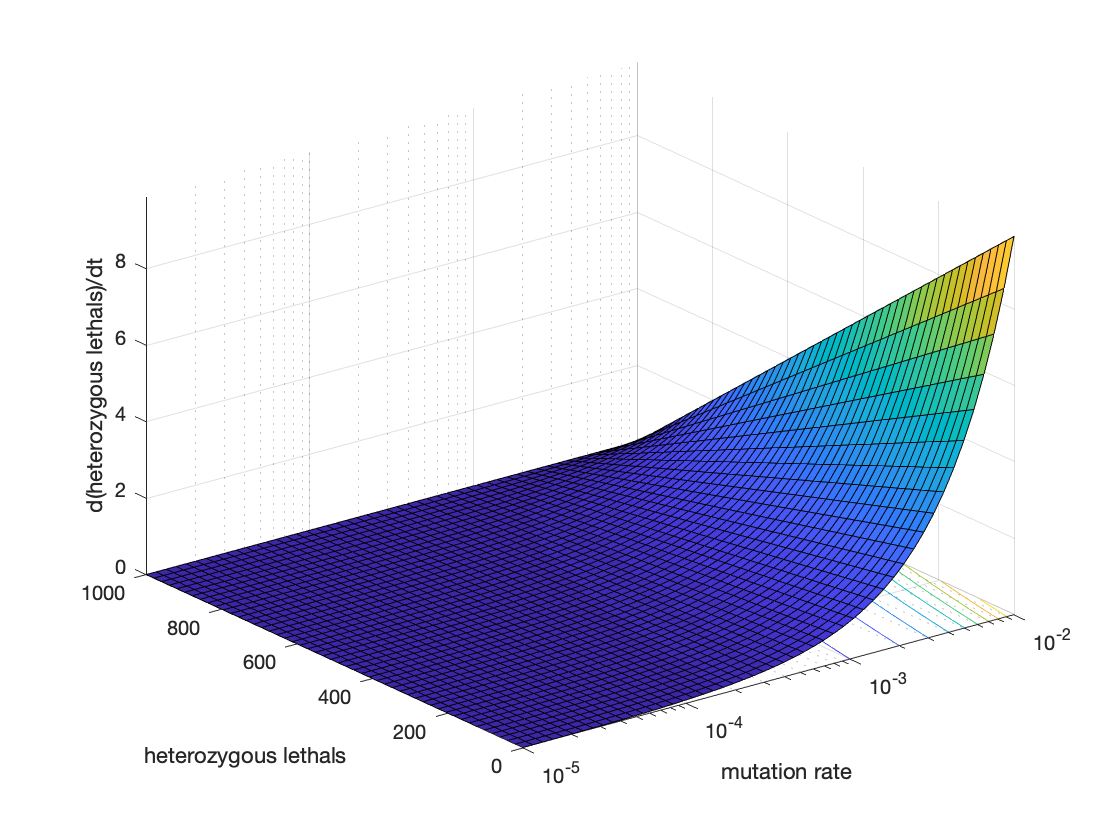

[x,l] = meshgrid(logspace(-5, -2), linspace(0,1000,50));
dldt = @(x,l) (1000 - l).*(x-x.^2);

figure
surfc(x, l, dldt(x,l))
set(gca, 'XScale', 'log')
xlabel("mutation rate")
ylabel("heterozygous lethals")
zlabel("d(heterozygous lethals)/dt")
grid on

The above equation is of the form of a semi-linear first order PDE which means we can use the method of characteristics to find an exact solution. First we parameterize the origional function into the derivative of each variable with respect to s, set equal to the forosponding function of (x,t,l) in the origional PDE. 

    dx/0 = dt/1 = dl/((1000-l)(x-x^2))

We then solve for two functions psi(x,t,l), and phi(x,t,l) such that dpsi = dphi = 0. 

    psi = 1000(x-x^2)t - l((x-x^2)t + 1)

    phi = x

Solving for l gives an equation in terms of (x,t) containing 1 arbitrary function which we can solve for using the initial condition l(t=0) = 0.

    l = (1000(x-x^2)t - f(x)) / ((x-x^2)t + 1)

    f(x) = 0

This equation also satisfies the boundry condition l(x=0) = 0.

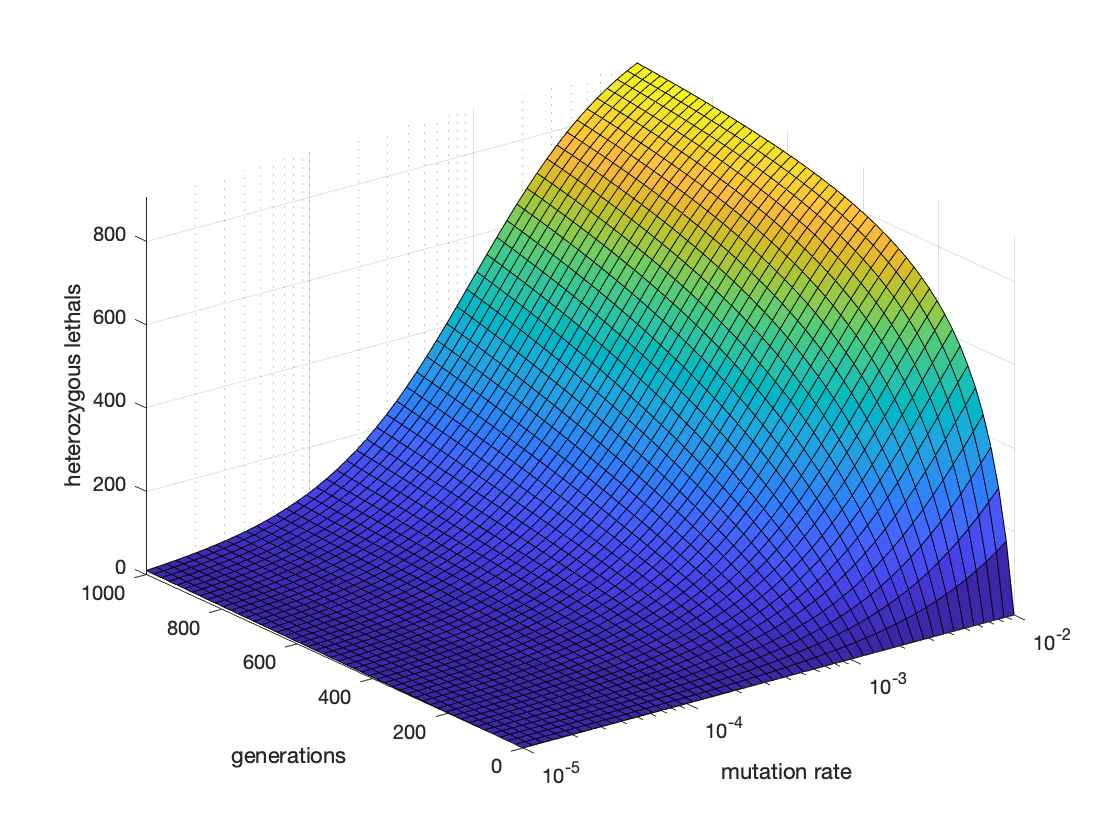

[x,t] = meshgrid(logspace(-5,-2), linspace(0,1000,50));
l = @(x,t) (1000.*(x-x.^2).*t)./((x-x.^2).*t+1);

figure
surfc(x, t, l(x,t))
set(gca, 'XScale', 'log')
xlabel("mutation rate")
ylabel("generations")
zlabel("heterozygous lethals")
grid on

Now that we have the value for lhet we can solve for fitness in terms of x, and lhet. The fitness depends on a constant term alpha that can be tweaked later to adjust for changing enviromental conditions (chemo).

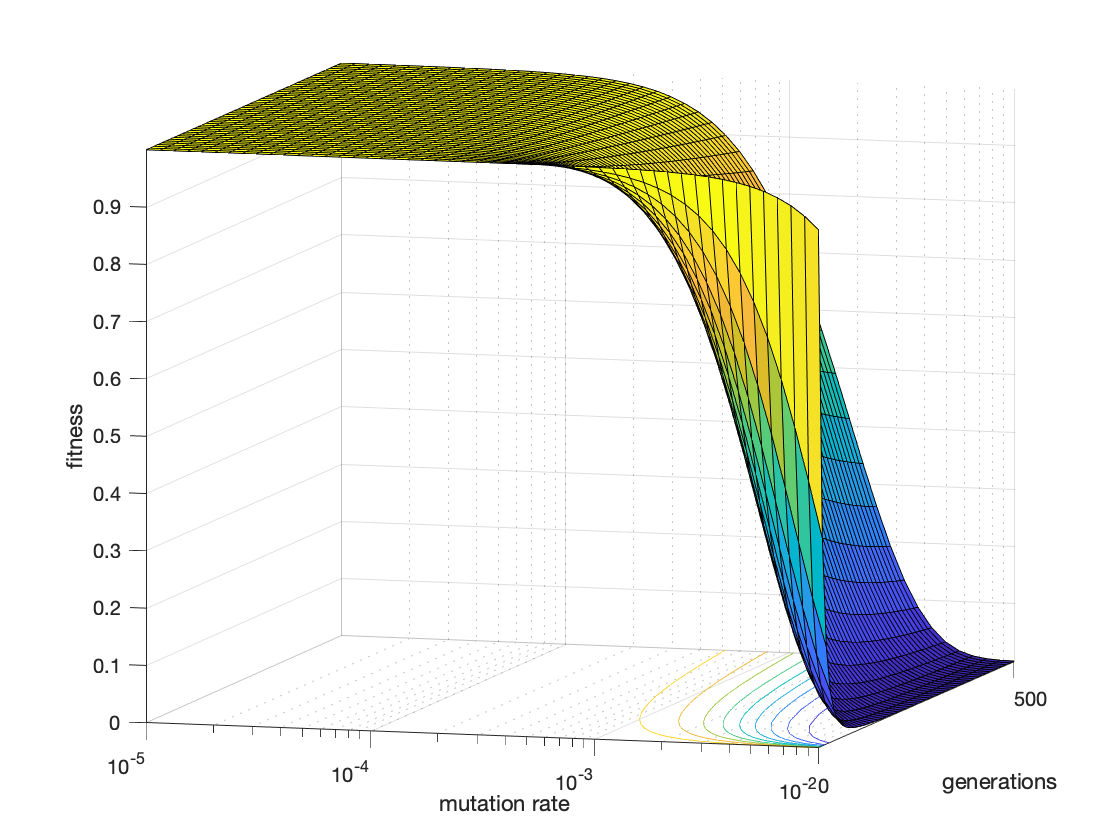

[x,t] = meshgrid(logspace(-5, -2), linspace(0,500,50));
alpha = 1;
fit = @(x,t) alpha.*((1-x.^2).^(1000-l(x,t))).*((1-x).^l(x,t));

figure
surfc(x, t, fit(x,t))
set(gca, 'XScale', 'log')
xlabel("mutation rate")
ylabel("generations")
zlabel("fitness")
grid on

Solving for y from PDE dy/dt = 